% Loading SnP 500 data for 6 months and performing EDA


% Load the data
data = readtable('/Users/amanarya/quant/projects/HMMs/^SPX.csv');

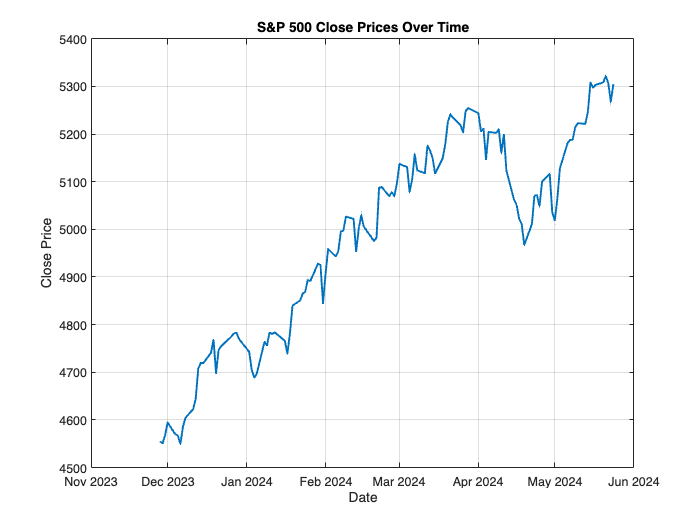


% Convert the 'Date' column to datetime format
data.Date = datetime(data.Date, 'InputFormat', 'yyyy-MM-dd');

% Plot the 'Close' prices over time
figure;
plot(data.Date, data.Close, 'LineWidth', 1.5);
title('S&P 500 Close Prices Over Time');
xlabel('Date');
ylabel('Close Price');
grid on;

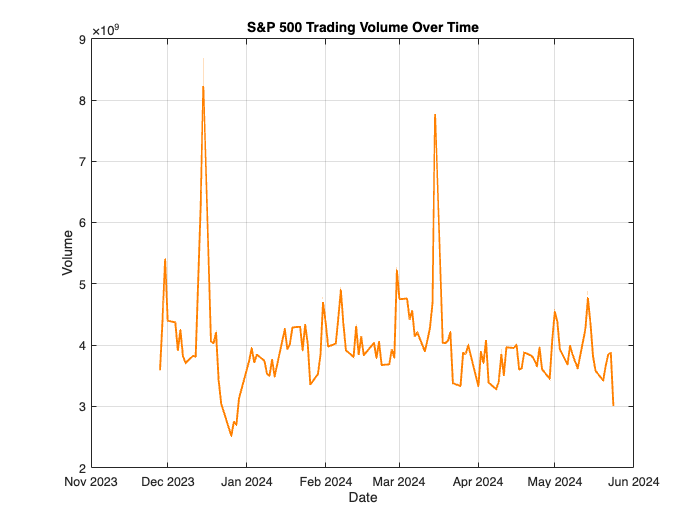


% Plot the 'Volume' over time
figure;
plot(data.Date, data.Volume, 'LineWidth', 1.5, 'Color', [1, 0.5, 0]); % RGB for orange
title('S&P 500 Trading Volume Over Time');
xlabel('Date');
ylabel('Volume');
grid on;

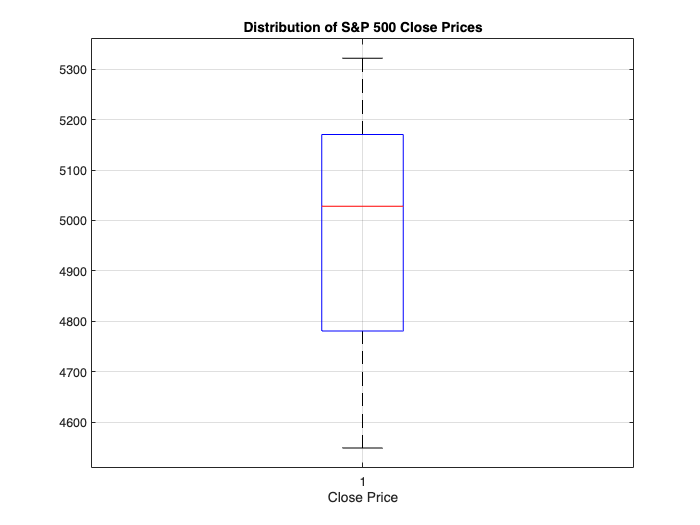


% Box plot for 'Close' prices
figure;
boxplot(data.Close);
title('Distribution of S&P 500 Close Prices');
xlabel('Close Price');
grid on;

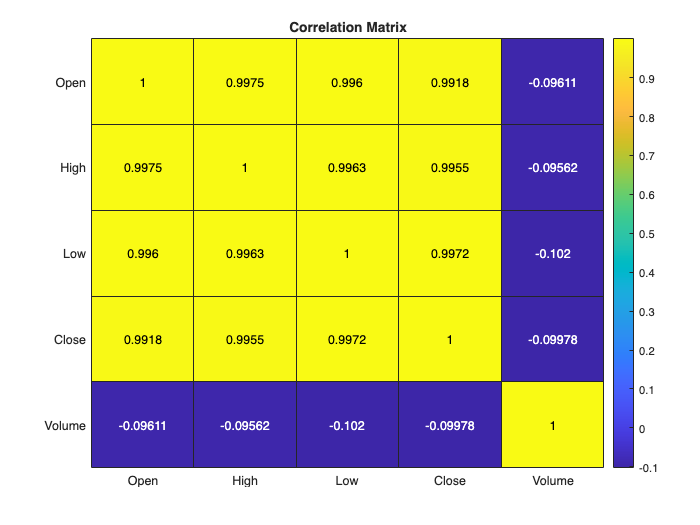


% Compute and plot the correlation matrix
corrMatrix = corr(data{:, {'Open', 'High', 'Low', 'Close', 'Volume'}});
figure;
heatmap({'Open', 'High', 'Low', 'Close', 'Volume'}, ...
    {'Open', 'High', 'Low', 'Close', 'Volume'}, corrMatrix, ...
    'ColorbarVisible', 'on', 'Colormap', parula, 'GridVisible', 'on');
title('Correlation Matrix');


% Display summary statistics
summaryStats = summary(data);

% Display summary statistics
disp(summaryStats);

        Date: [1×1 struct]
        Open: [1×1 struct]
        High: [1×1 struct]
         Low: [1×1 struct]
       Close: [1×1 struct]
    AdjClose: [1×1 struct]
      Volume: [1×1 struct]

